# Try6 version1 （不规则图形，高斯迭代，矩阵法，相容误差）

基于 版本try3.1

看起来似乎可行，用echelon和改变cond d arret 实现。使用echelon因为while中套for耗时久。

热方程仍有疑问

## Paramètre


x=10;   %longueur en x
y=5;   %longueur en y
h=.1;  %pas
phi_k=-1; %carac thermique -phi/k
% si cette valeur positive, creux
m=0:h:x;
n=0:h:y;
T=zeros(length(n),length(m));

Echelon=ones(length(n),length(m));

disp(['length(T)=',num2str(length(T))])

length(T)=101


## Condition frontière


T(1,:)=10;
T(:,1)=10;
T(length(n),:)=5;
T(:,length(m))=1;
% T(25:50,1)=100;
% for i=1:20
%     for j=75:101
%         Echelon(i,j)=0;
%     end
% end
Echelon(1:20,75:101)=0

Echelon =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

T=T.*Echelon;
T1=T

T1 =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

[xq,yq] = meshgrid(m, n)

xq =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    

yq =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    

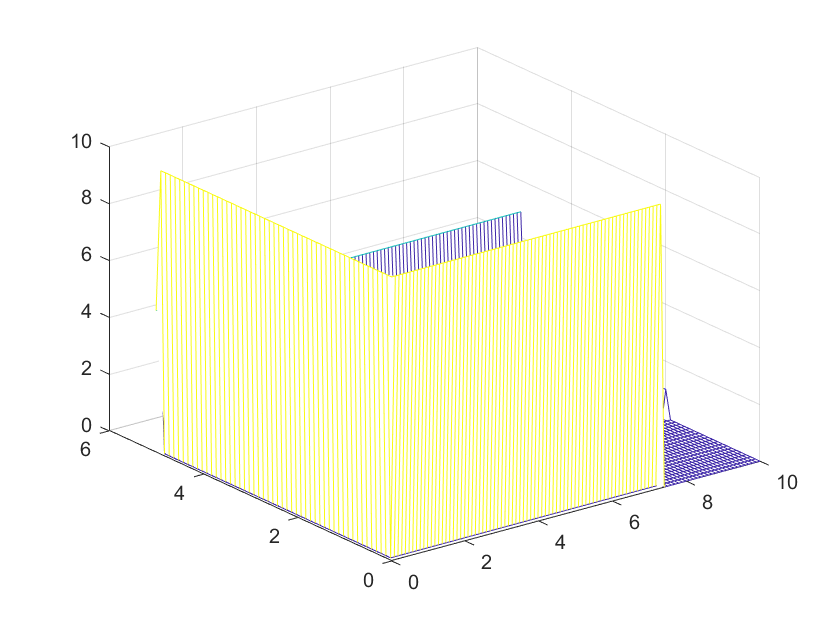

mesh(xq,yq,T1)

## Gausse-Seidel

e=1; count=0; temp=0;
while count<=50000
    count=count+1;
    T=T.*Echelon;
    temp=T(round(length(n)/2),round(length(m)/2));
    T1(2:length(n)-1,2:length(m)-1)=(T(2:length(n)-1,1:length(m)-2) ...%West
        +T(2:length(n)-1,3:length(m)) ...%East
        +T(1:length(n)-2,2:length(m)-1) ...%North
        +T(3:length(n),2:length(m)-1))/4-(h^2*phi_k)/4; %South
    
%     e=abs((T1(round(length(n)/2),round(length(m)/2))-temp)/T1(round(length(n)/2),round(length(m)/2)));
    T=T1;
end
count

count = 50001

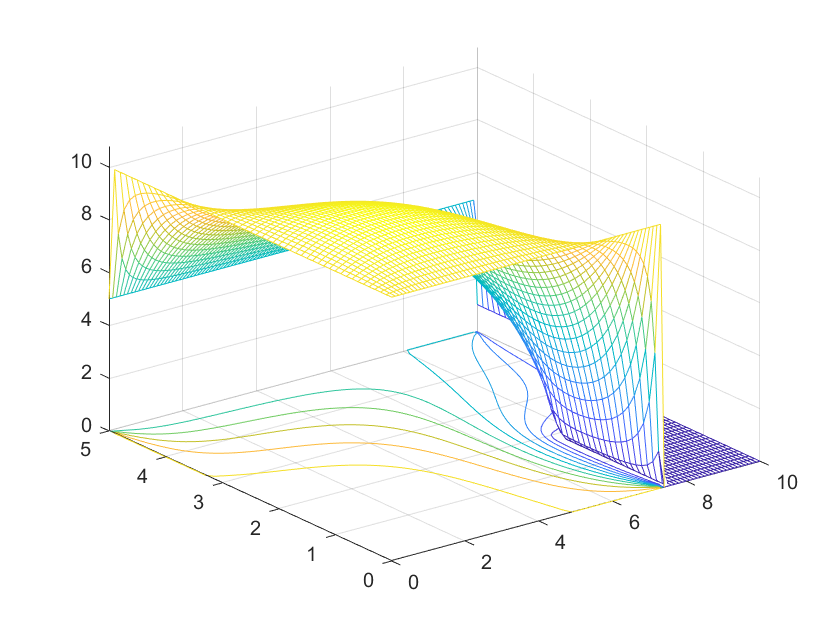


meshc(xq,yq,T)